# **Video Processing: Laboratory 1:**

Adrià Garcia Coscolla: u232256

Ernest Fosch Muntané: u196572

### **Task 1:**

a=6

a = 6

b=2

b = 2

N=11 %We will have NxN samples

N = 11


[m,n]= meshgrid(-N/2:N/2-1, -N/2:N/2-1)

m =    -5.5000   -4.5000   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000    4.5000
   -5.5000   -4.5000   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000    4.5000
   -5.5000   -4.5000   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000    4.5000
   -5.5000   -4.5000   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000    4.5000
   -5.5000   -4.5000   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000    4.5000
   -5.5000   -4.5000   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000    4.5000
   -5.5000   -4.5000   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000    4.5000
   -5.5000   -4.5000   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000    4.5000
   -5.5000   -4.5000   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000    4.50

n =    -5.5000   -5.5000   -5.5000   -5.5000   -5.5000   -5.5000   -5.5000   -5.5000   -5.5000   -5.5000   -5.5000
   -4.5000   -4.5000   -4.5000   -4.5000   -4.5000   -4.5000   -4.5000   -4.5000   -4.5000   -4.5000   -4.5000
   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000
   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000
   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000
    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.50

%[x,y]= meshgrid(-N/2:1/40:N/2-1, -N/2:1/20:N/2-1)

psi= @(x,y)cos(2*pi*a*x) .* cos(2*pi*b*y) + ...
0.7*sin(pi*a*b*(x+y)) + ...
0.5*cos(pi*(a + 0.5*a*b)*x - pi*b*y); 

V=[1/40,0;0,1/20]

V =     0.0250         0
         0    0.0500



x = V(1,1)*m + V(1,2)*n

x =    -0.1375   -0.1125   -0.0875   -0.0625   -0.0375   -0.0125    0.0125    0.0375    0.0625    0.0875    0.1125
   -0.1375   -0.1125   -0.0875   -0.0625   -0.0375   -0.0125    0.0125    0.0375    0.0625    0.0875    0.1125
   -0.1375   -0.1125   -0.0875   -0.0625   -0.0375   -0.0125    0.0125    0.0375    0.0625    0.0875    0.1125
   -0.1375   -0.1125   -0.0875   -0.0625   -0.0375   -0.0125    0.0125    0.0375    0.0625    0.0875    0.1125
   -0.1375   -0.1125   -0.0875   -0.0625   -0.0375   -0.0125    0.0125    0.0375    0.0625    0.0875    0.1125
   -0.1375   -0.1125   -0.0875   -0.0625   -0.0375   -0.0125    0.0125    0.0375    0.0625    0.0875    0.1125
   -0.1375   -0.1125   -0.0875   -0.0625   -0.0375   -0.0125    0.0125    0.0375    0.0625    0.0875    0.1125
   -0.1375   -0.1125   -0.0875   -0.0625   -0.0375   -0.0125    0.0125    0.0375    0.0625    0.0875    0.1125
   -0.1375   -0.1125   -0.0875   -0.0625   -0.0375   -0.0125    0.0125    0.0375    0.0625    0.0875    0.11

y = V(2,1)*m + V(2,2)*n

y =    -0.2750   -0.2750   -0.2750   -0.2750   -0.2750   -0.2750   -0.2750   -0.2750   -0.2750   -0.2750   -0.2750
   -0.2250   -0.2250   -0.2250   -0.2250   -0.2250   -0.2250   -0.2250   -0.2250   -0.2250   -0.2250   -0.2250
   -0.1750   -0.1750   -0.1750   -0.1750   -0.1750   -0.1750   -0.1750   -0.1750   -0.1750   -0.1750   -0.1750
   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250
   -0.0750   -0.0750   -0.0750   -0.0750   -0.0750   -0.0750   -0.0750   -0.0750   -0.0750   -0.0750   -0.0750
   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250
    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250
    0.0750    0.0750    0.0750    0.0750    0.0750    0.0750    0.0750    0.0750    0.0750    0.0750    0.0750
    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.12

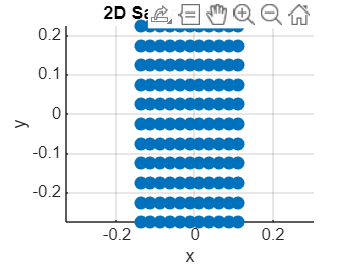


psi_s = psi(x, y); %sampling of the function: psi_s = psi(Vn)

%2D plot of the sample lattice grid.
figure;
scatter(x(:), y(:), 50, 'filled');  % 50 = marker size
axis equal;
xlabel('x'); ylabel('y');
title('2D Sampling Lattice');
grid on;

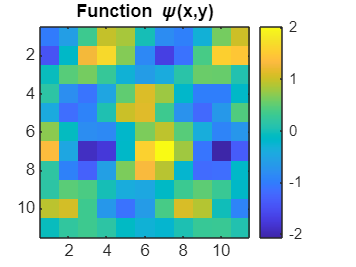


%2D plot of the sampled signal (psi)
imagesc(psi_s);
colorbar;
axis equal tight;  % optional, keeps aspect ratio correct
title('Function \psi(x,y)');

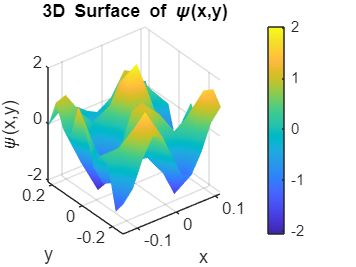


%3D plot of the sampled signal (psi)
figure;
surf(x, y, psi_s);        % create 3D surface
shading interp;            % smooth shading
colorbar;                  % show color scale
axis tight;                % fit axes tightly
xlabel('x'); ylabel('y'); zlabel('\psi(x,y)');
title('3D Surface of \psi(x,y)');